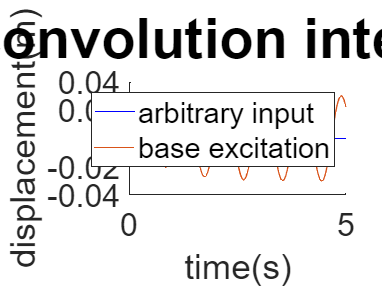

% © 2022 2018100778 최동욱 기계공학과 <ch3044637@khu.ac.kr>
% 2022-1학기 기계진동 term_project
% 자동차의 진동의 컨볼루션 적분에 대한 응답

clear; clc;

% initial condition
m = 800; k = 4e4; c = 2e3; v = 20;
l = 0.005; hour2sec = 3600;
A = 0.01;

% natural frequency, driving frequency, damping ratio, damped natural frequency
Wn = sqrt(k/m);
Wb = v*2*pi/(l*hour2sec);
zeta = c/(2*sqrt(k*m));
Wd = Wn*sqrt(1-zeta^2);
t0 = pi/Wb;
% seta = 0;
seta = atan(k/(c*Wb));

% convolution integral
syms t
xp =  A*sqrt((c*Wb)^2+k^2)/(2*m*Wd)*exp(-zeta*Wn*t)...
    *((sin(-Wd*t+seta+(Wb+Wd)*t0)-sin(-Wd*t+seta))/(Wb+Wd)-...
    (sin(Wd*t+seta+(Wb-Wd)*t0)-sin(Wd*t+seta))/(Wb-Wd));


% plot
hold on
fplot(t, xp, 'b');
set(gca,'FontSize',24);
xlabel('time(s)');
ylabel('displacement(m)');
axis([0 5 -0.04 0.04]);
term_project_1_3;
title('convolution integral','FontSize',42,'FontWeight','bold');
legend('arbitrary input','base excitation');
hold off